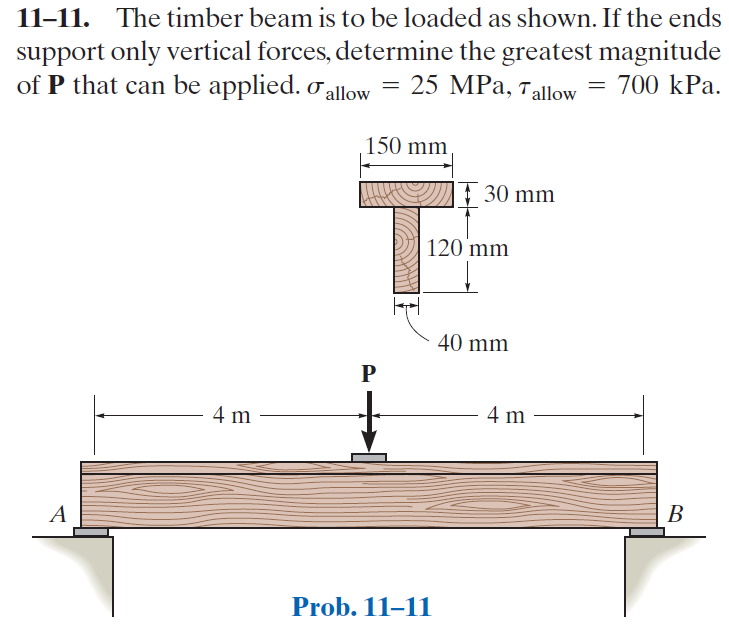

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-11P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-11P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

P = sym('P', 'positive');
P_max = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -P, 4*u.m);
b = b.add('reaction', 'force', 'Rb', 8*u.m);
b.L = 8*u.m;

# section properties

yc = [120/2; 120+30/2]*u.mm;
Ac = [40*120; 150*30]*u.mm^2;
Ic = [40*120^3; 150*30^3]/12*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{3100000000\,P\,x\,\left(48\,m^{2}-x^{2}\right)}{712827\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }x\leq 4\,m\\ -\frac{3100000000\,P\,\left(x-8\,m\right)\,\left(x^{2}-16\,x\,m+16\,m^{2}\right)}{712827\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }4\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{3100000000\,P\,\left(x-4\,m\right)\,\left(x+4\,m\right)}{237609\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }x\leq 4\,m\\ -\frac{3100000000\,P\,\left(x-4\,m\right)\,\left(x-12\,m\right)}{237609\,\text{E}}\,\frac{1}{m^{4}} & \text{ if }4\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{P\,x}{2} & \text{ if }x\leq 4\,m\\ -\frac{P\,\left(x-8\,m\right)}{2} & \text{ if }4\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{P}{2} & \text{ if }x\leq 4\,m\\ -\frac{P}{2} & \text{ if }4\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{P}{2}\\ \mathrm{Rb} & \frac{P}{2} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

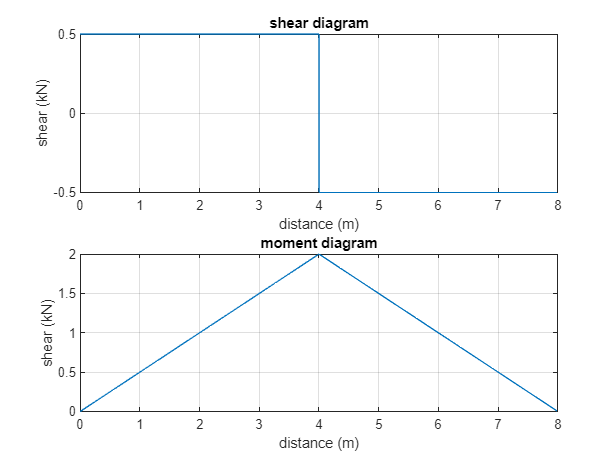

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'}, P, 1);

# maximum loads

M_max(P) = m(4*u.m)

$$M\_max(P) = 2\,P\,m$$

V_max(P) = v(0)

$$V\_max(P) = \frac{P}{2}$$

# maximum stresses

C = symmax([yn (120+30)*u.mm-yn]);
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max, u.mm)*C/b.I

$$sigma\_max(P) = \frac{796\,P}{79203}\,\frac{1}{{\mathrm{mm}}^{2}}$$

Q_max = (yn/2)*(40*u.mm*yn);
t_min = 40*u.mm;
tau_max = V_max*Q_max/(b.I*t_min)

$$tau\_max(P) = \frac{39601\,P}{327372400}\,\frac{1}{{\mathrm{mm}}^{2}}$$

# maximum concentrated force

sigma_allow = 25*u.MPa;
tau_allow = 700*u.kPa;
P_max.bending = solve(sigma_max == rewrite(sigma_allow, [u.kN u.mm]));
P_max.bending = simplify(P_max.bending);
P_max_bending = vpa(P_max.bending, 3) %#ok<NASGU> 

$$P\_max\_bending = 2.49\,\mathrm{kN}$$

P_max.shear = solve(tau_max == rewrite(tau_allow, [u.kN u.mm]));
P_max.shear = simplify(P_max.shear);
P_max_shear = vpa(P_max.shear, 3) %#ok<NASGU> 

$$P\_max\_shear = 5.79\,\mathrm{kN}$$

P_max_vals = [P_max.bending P_max.shear];
loc = sigma_max(P_max_vals) <= sigma_allow & ...
      tau_max(P_max_vals) <= tau_allow;
P_max.limit = P_max_vals(isAlways(loc));
P_max_limit = vpa(P_max.limit, 3) %#ok<NASGU> 

$$P\_max\_limit = 2.49\,\mathrm{kN}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear P_max_bending P_max_shear P_max_vals loc P_max_limit;